clc
clear

K_a=4; %V/V
K_m=0.36; %Hz/V
T_m=0.074; %s
K_w=3.75; %in/rotation ---> (in/s)/Hz
K_s=0.165; %V/in     linearized about x=in

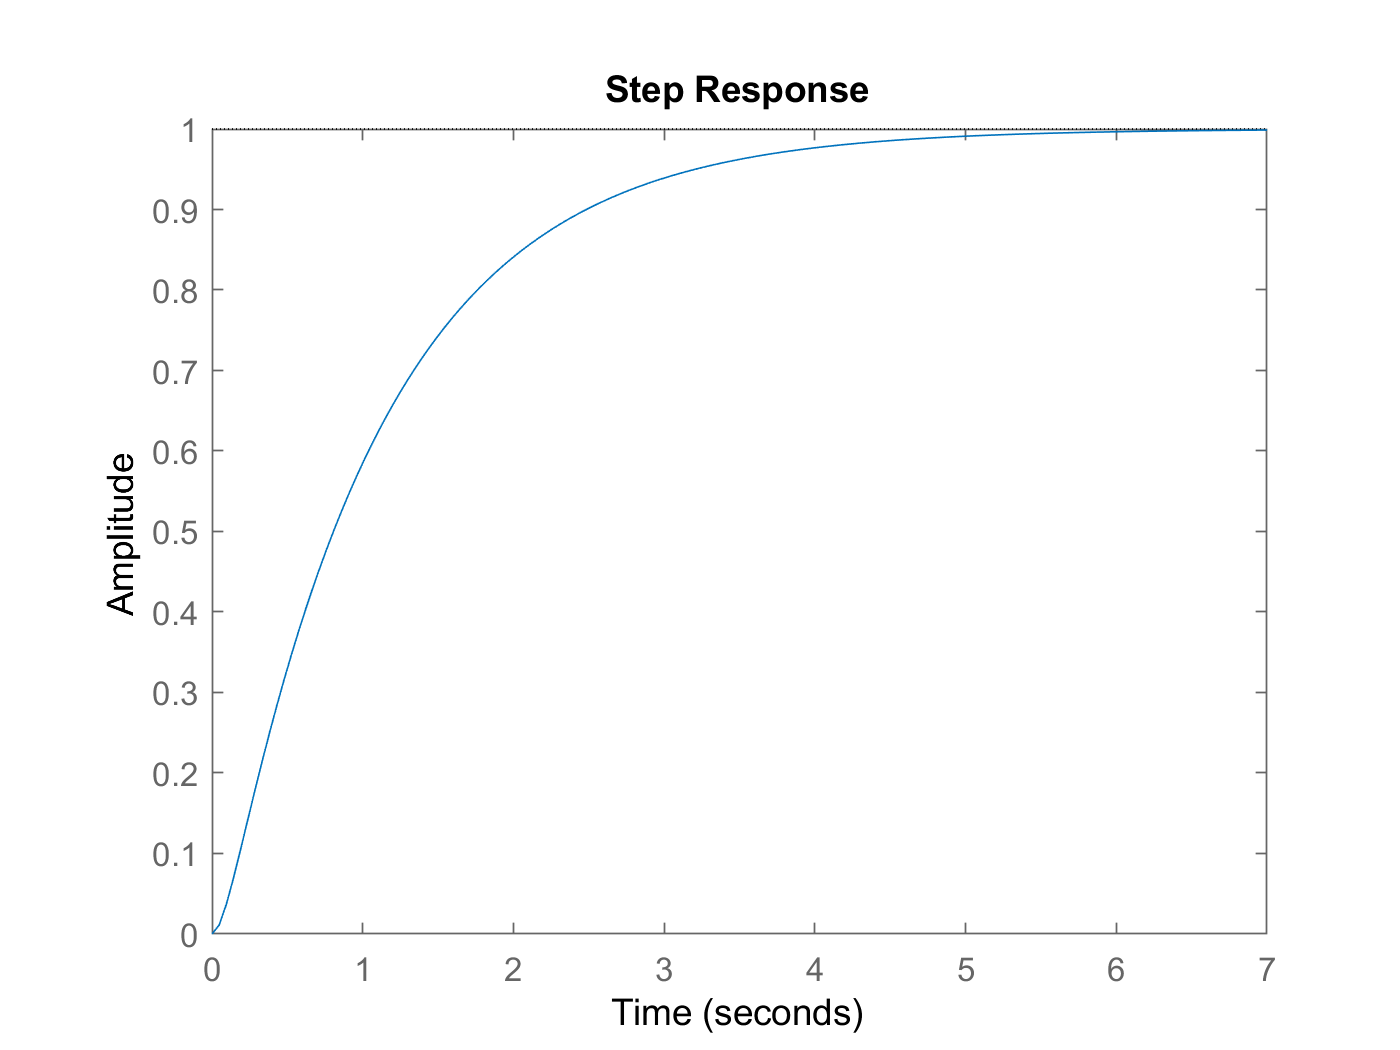

%examine the case that H(s) is unity gain
G_m=tf(K_m*K_a,[T_m 1]);
G_w=tf(K_w,[1 0]);
G_s=K_s;
G_ol=G_m*G_w*G_s;

K_p=1;
G_cl=tf(K_p*K_m*K_a*K_w*K_s,[T_m 1 K_p*K_m*K_a*K_w*K_s]);
step(G_cl)

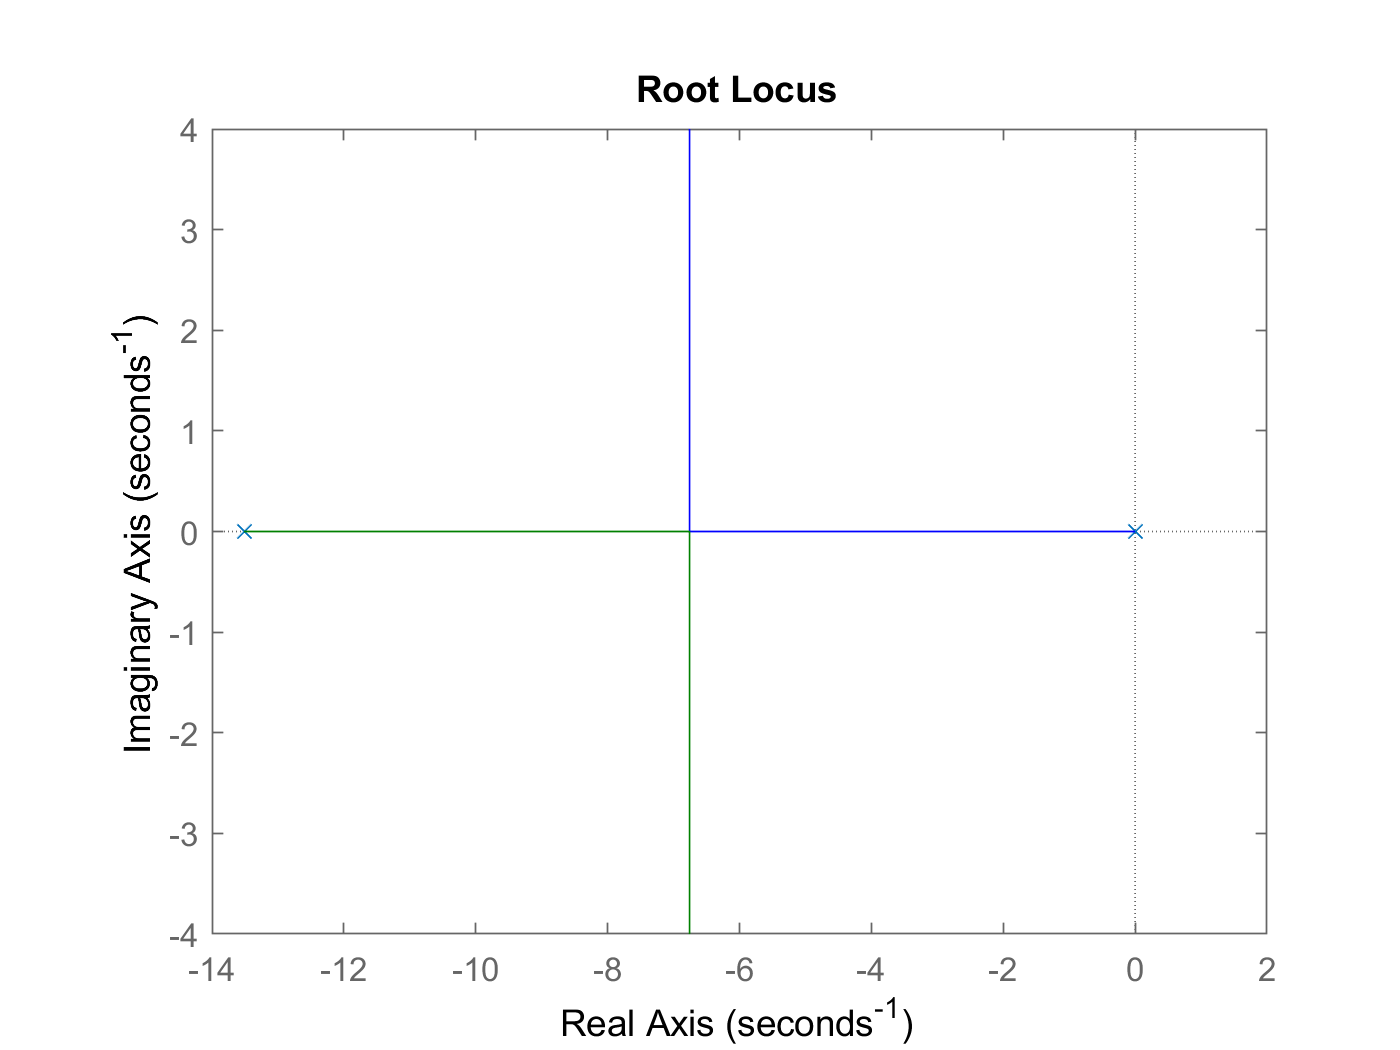

rlocus(G_ol)

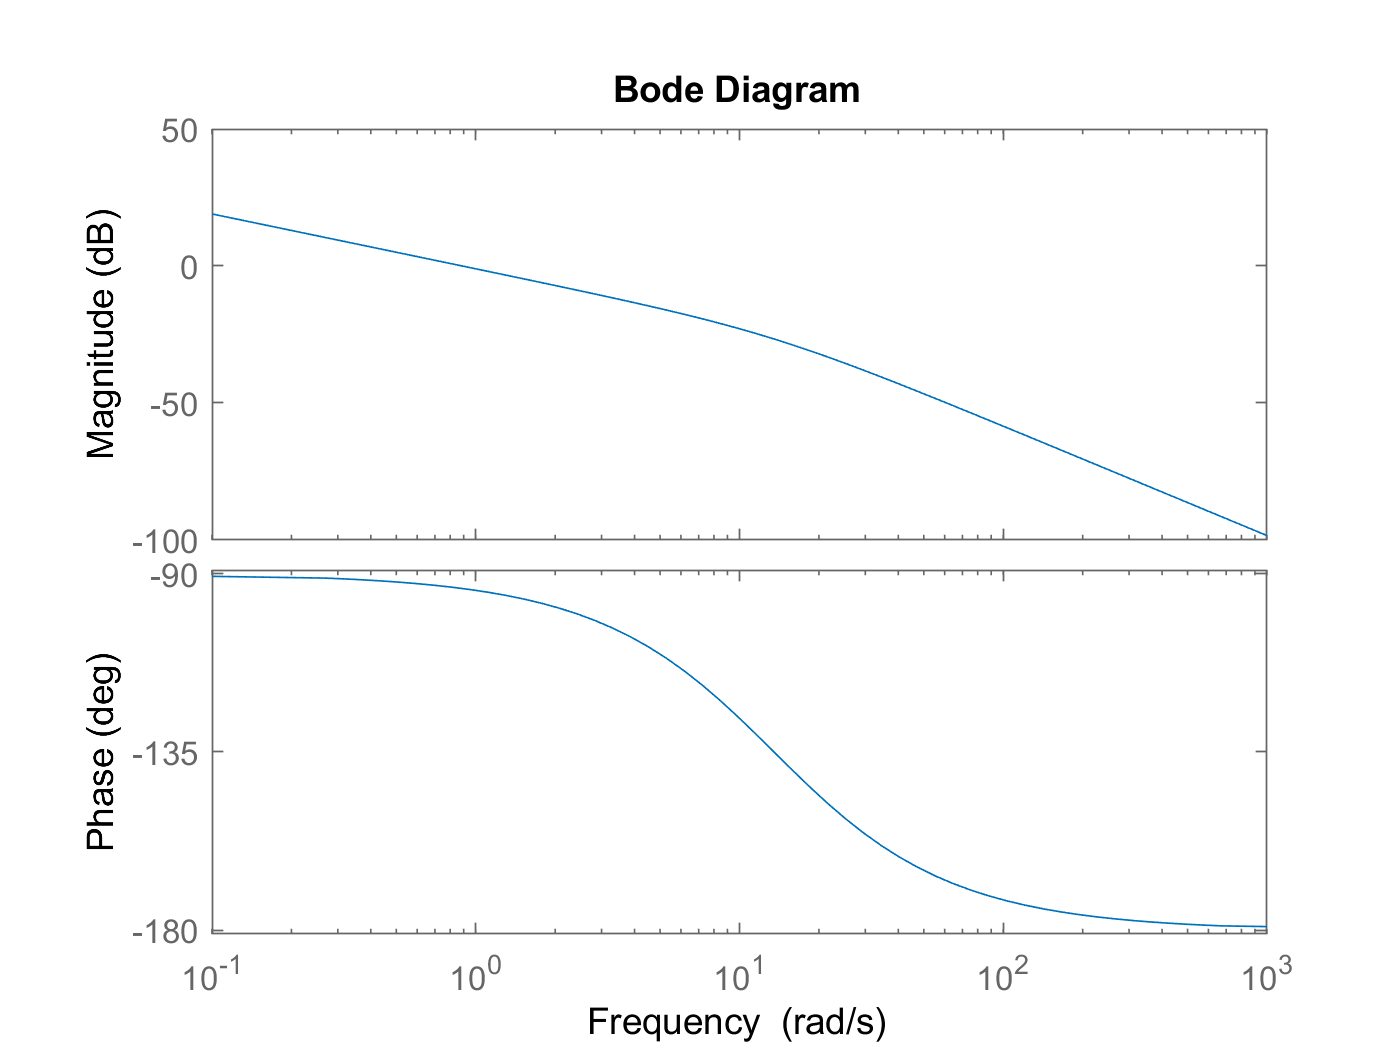

bode(G_ol)

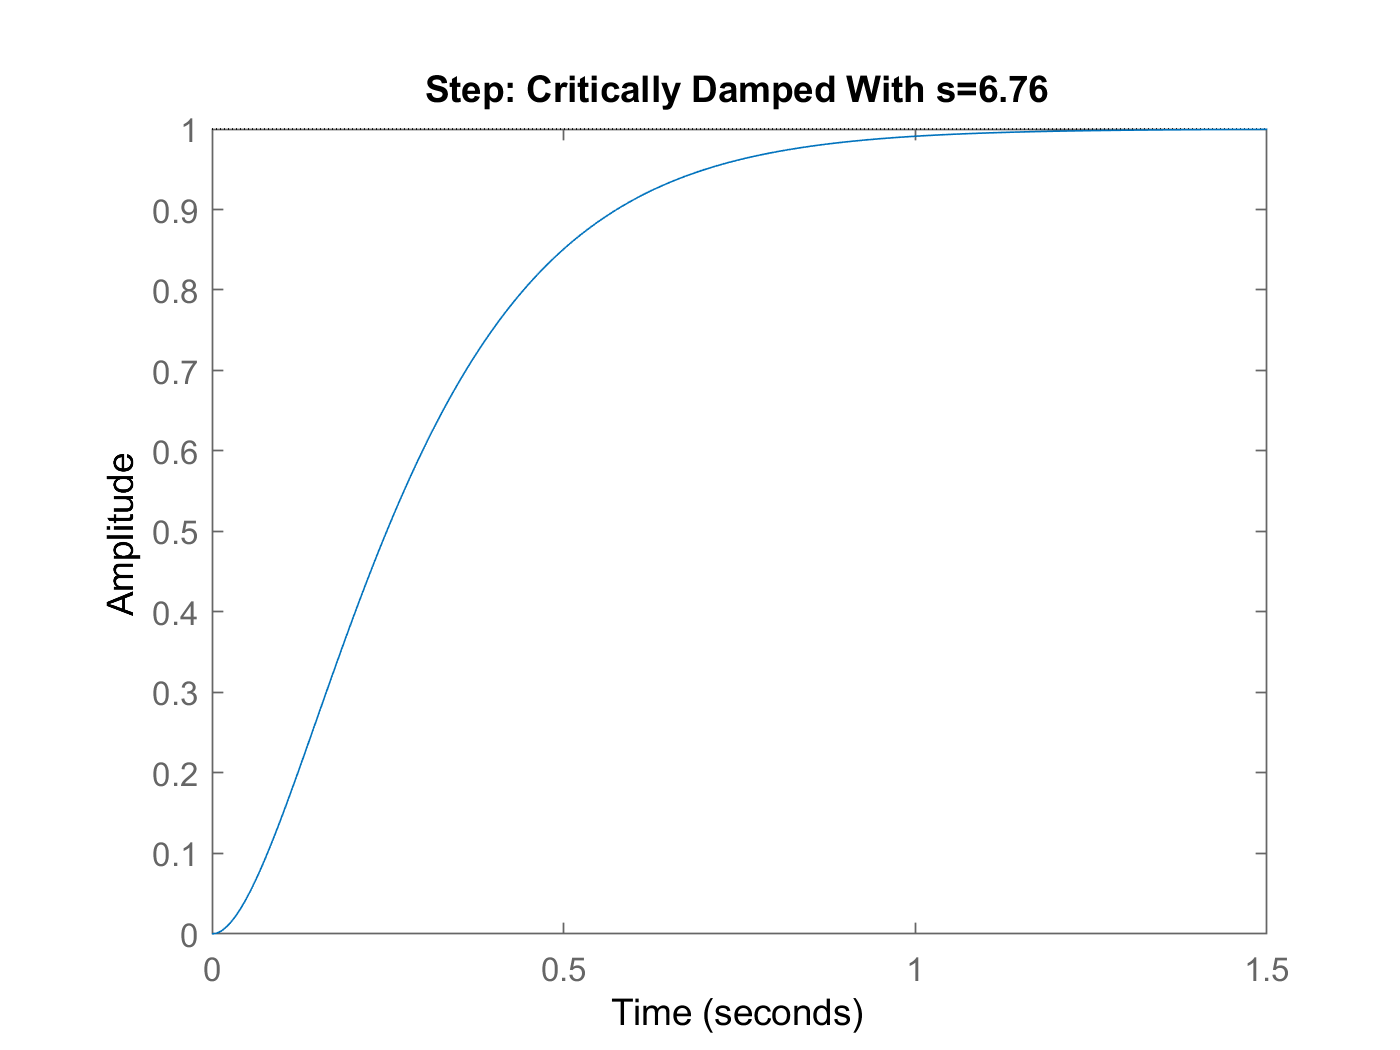

critical=tf(6.76^2,[1 2*6.76 6.76^2]);
step(critical)
title("Step: Critically Damped With s=6.76")

stepinfo(critical)

ans = struct with fields:
        RiseTime: 0.4968
    SettlingTime: 0.8630
     SettlingMin: 0.9019
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 1.7644


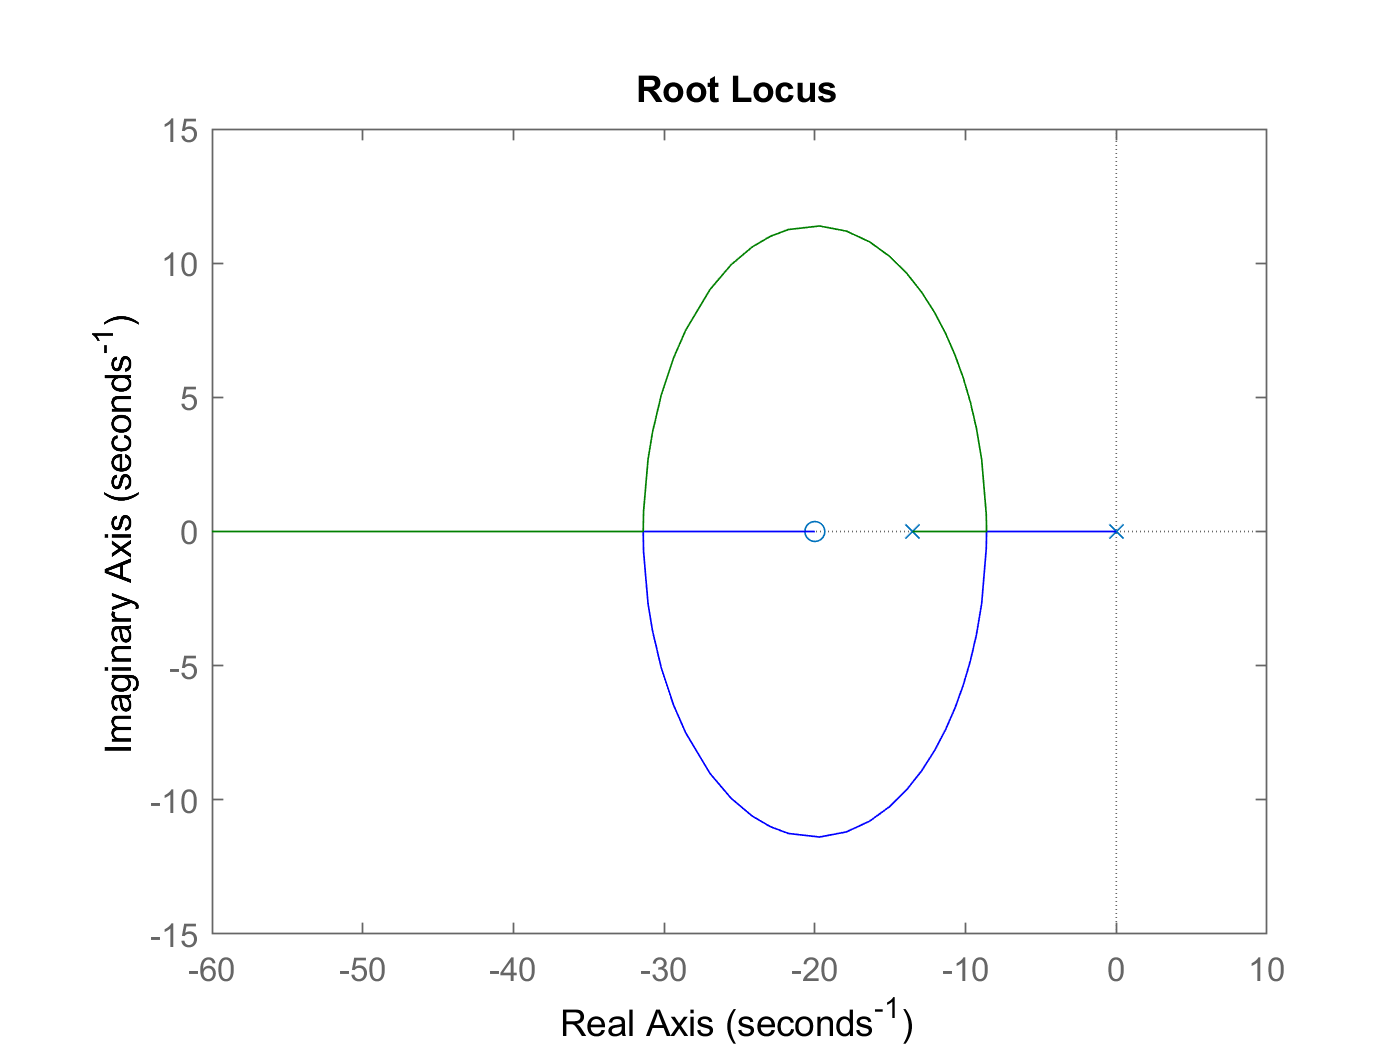

alpha=20;
G_rl=0.891*tf([1 alpha],[T_m 1 0]);
rlocus(G_rl)

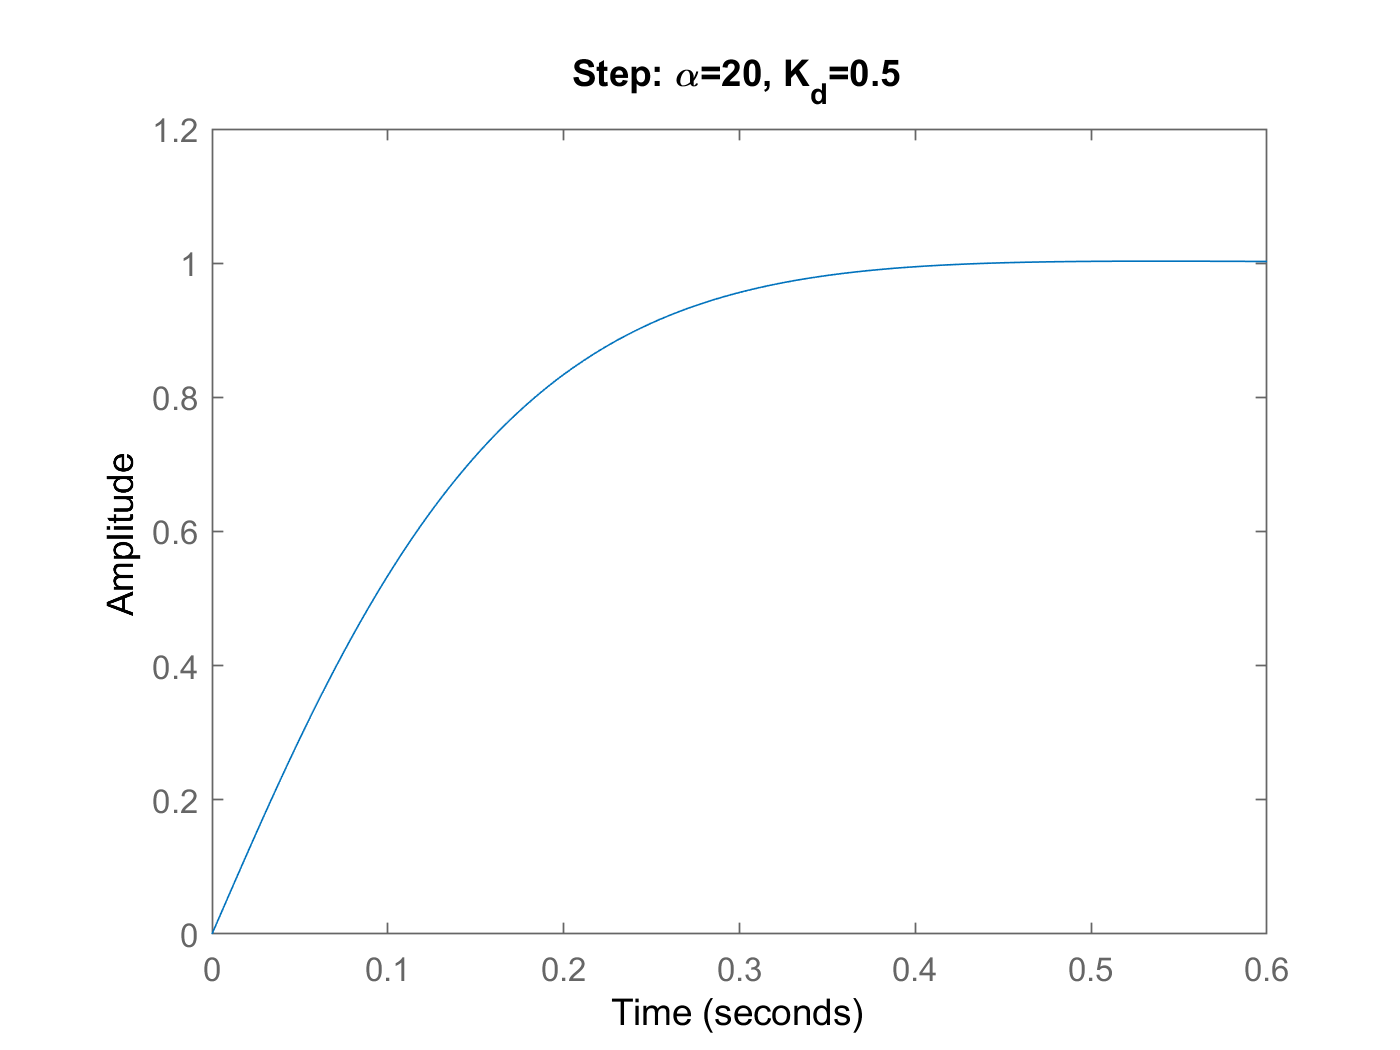

K_d=0.5;
K_p=10;

H=tf([K_d K_p],1);
G_cl=(G_ol)*H/(1+G_ol*H);
step(G_cl)
title("Step: \alpha=20, K_d=0.5")

stepinfo(G_cl)

ans = struct with fields:
        RiseTime: 0.2247
    SettlingTime: 0.3455
     SettlingMin: 0.9049
     SettlingMax: 1.0030
       Overshoot: 0.2996
      Undershoot: 0
            Peak: 1.0030
        PeakTime: 0.5375


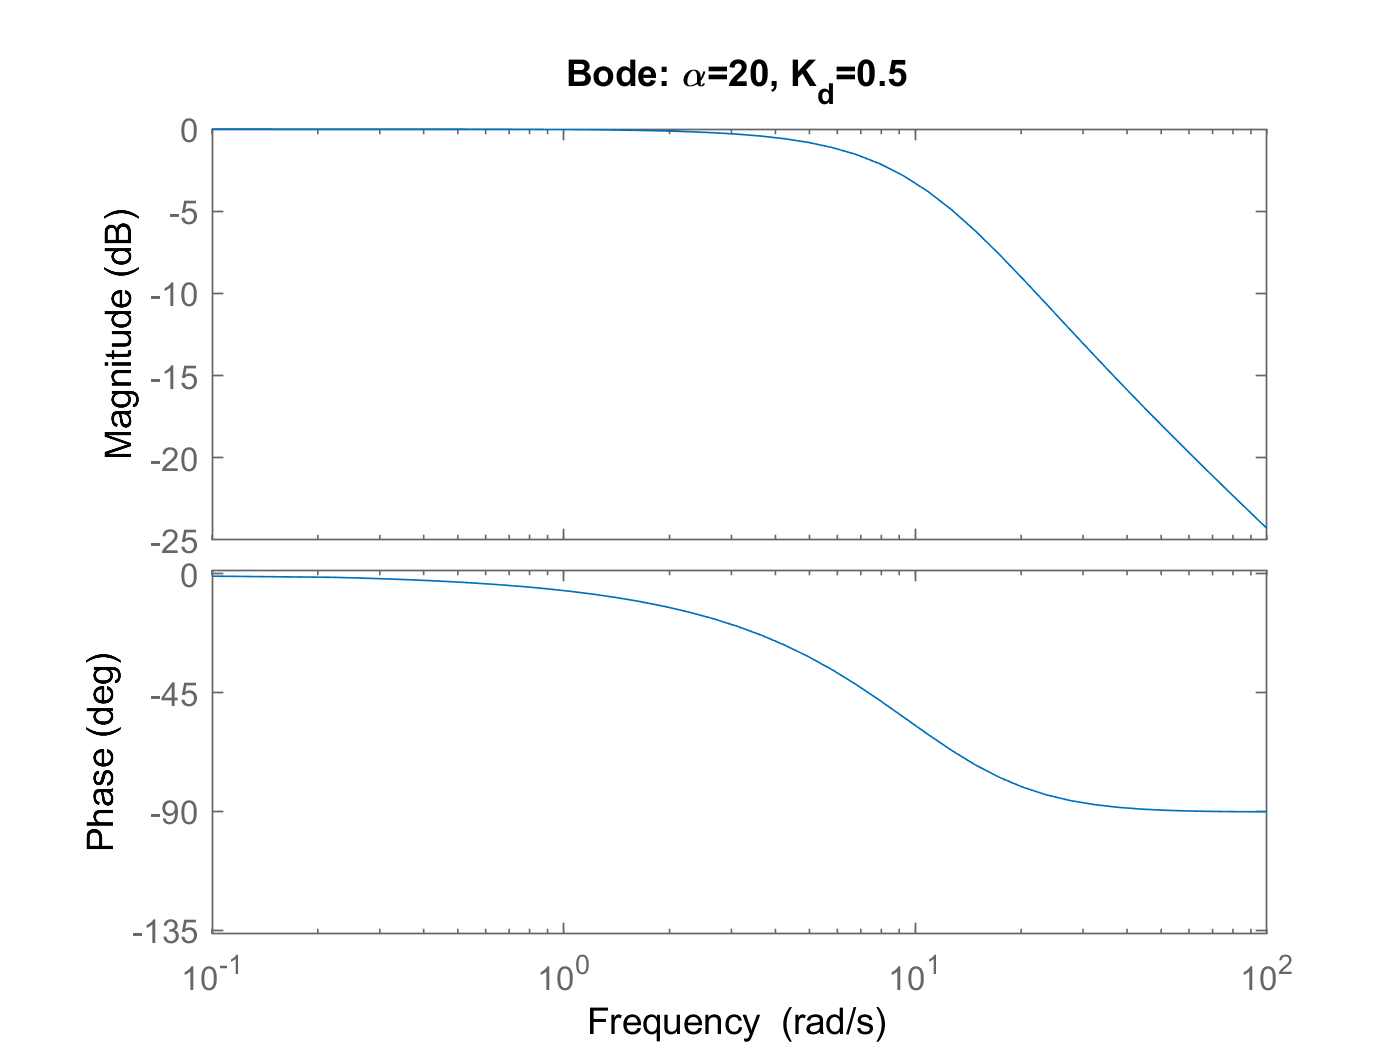

bode(G_cl)
title("Bode: \alpha=20, K_d=0.5")

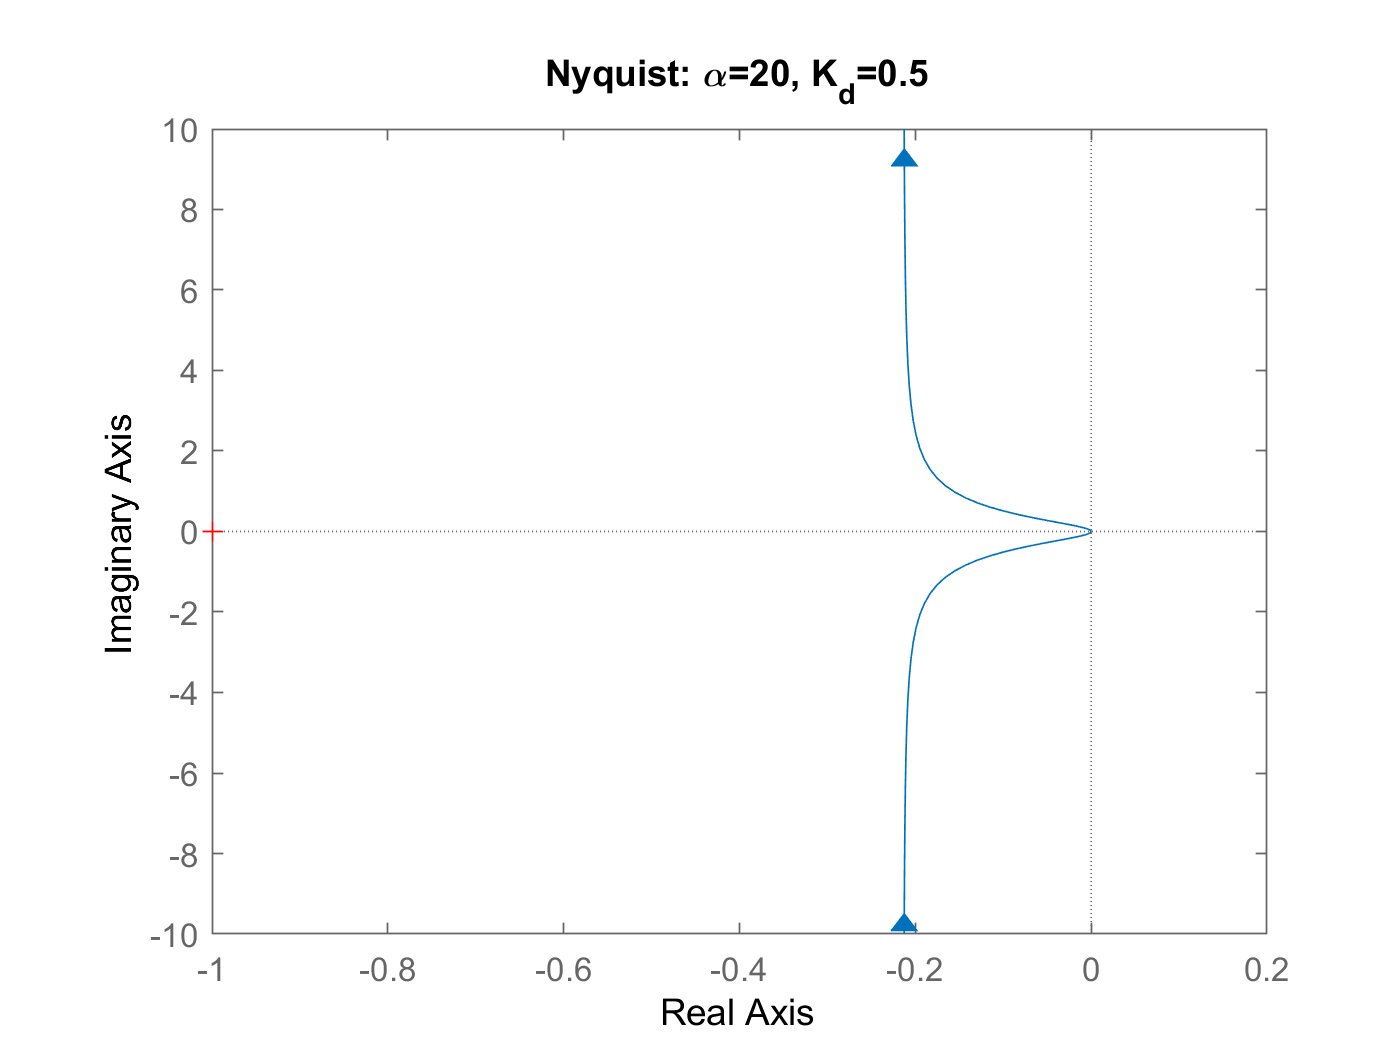

L=0.89*tf([K_d K_p],[T_m 1 0]);
nyquist(L)
title("Nyquist: \alpha=20, K_d=0.5")

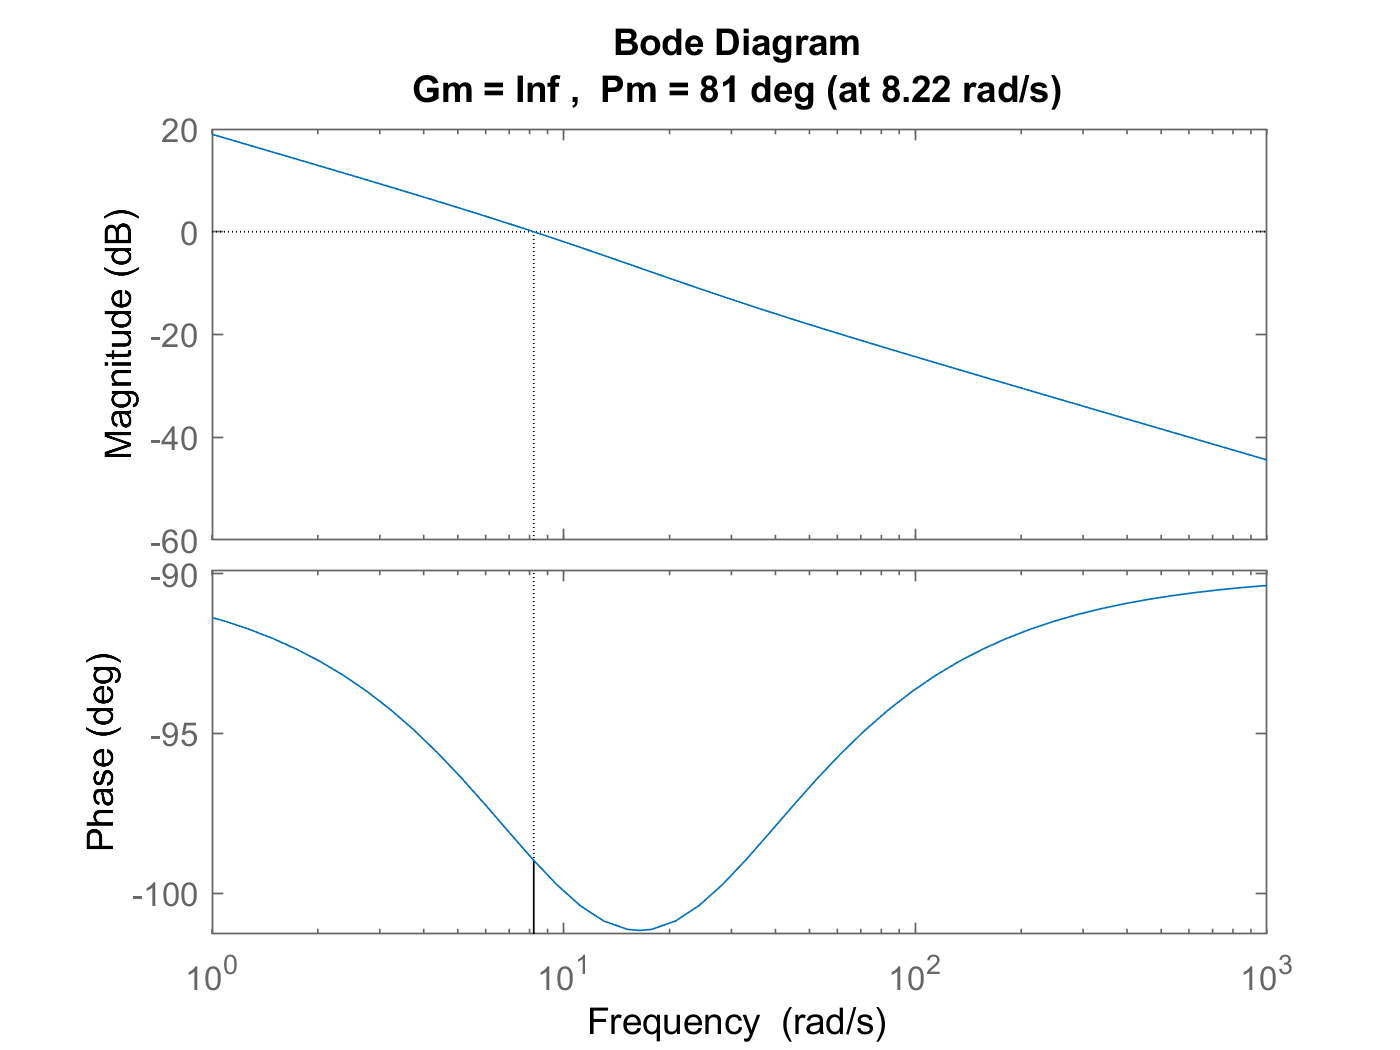

margin(L)

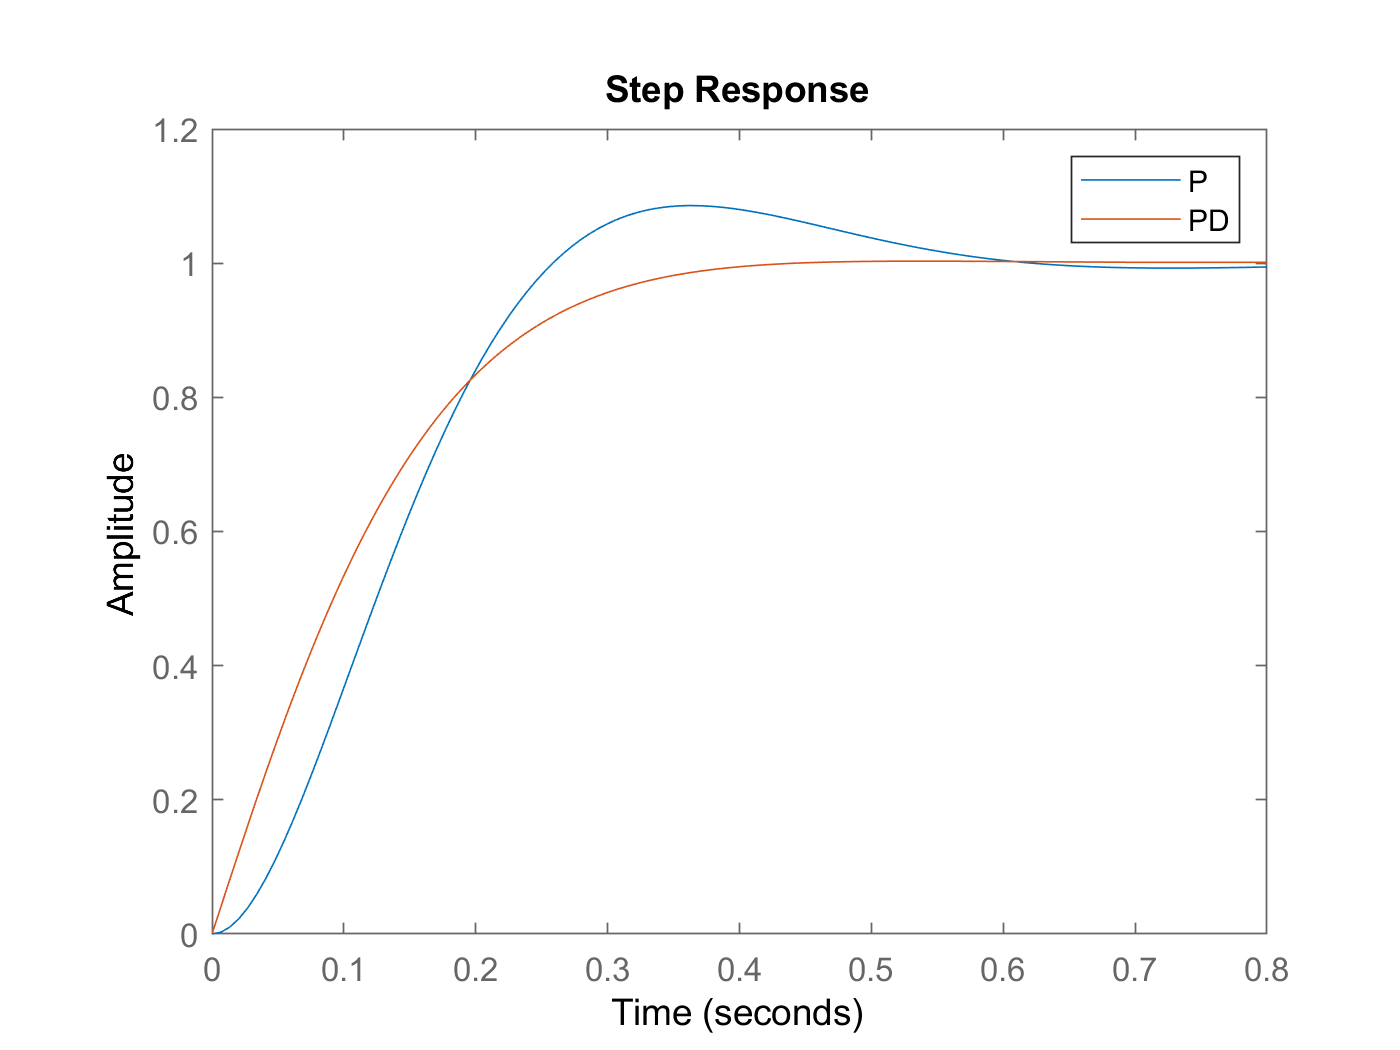

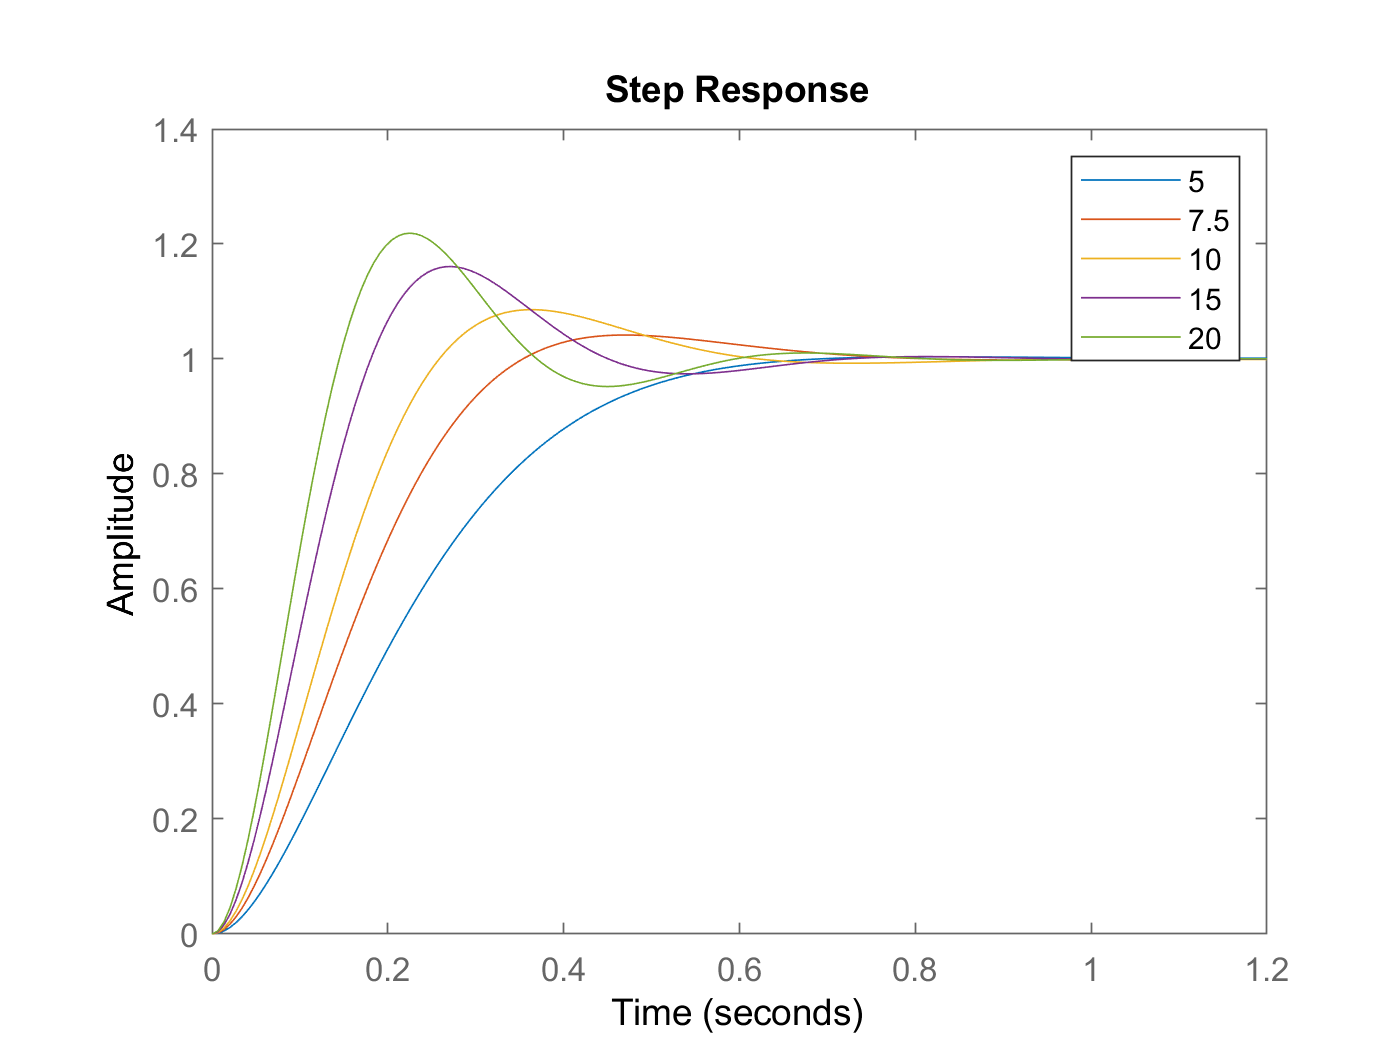

K_d=0.5;
K_p=10;

H1=K_p;
G_clbutterworth=(G_ol)*H1/(1+G_ol*H1);
step(G_clbutterworth)
hold on
H2=tf([K_d K_p],1);
G_cl2=(G_ol)*H2/(1+G_ol*H2);
step(G_cl2)
legend("P","PD")
hold off

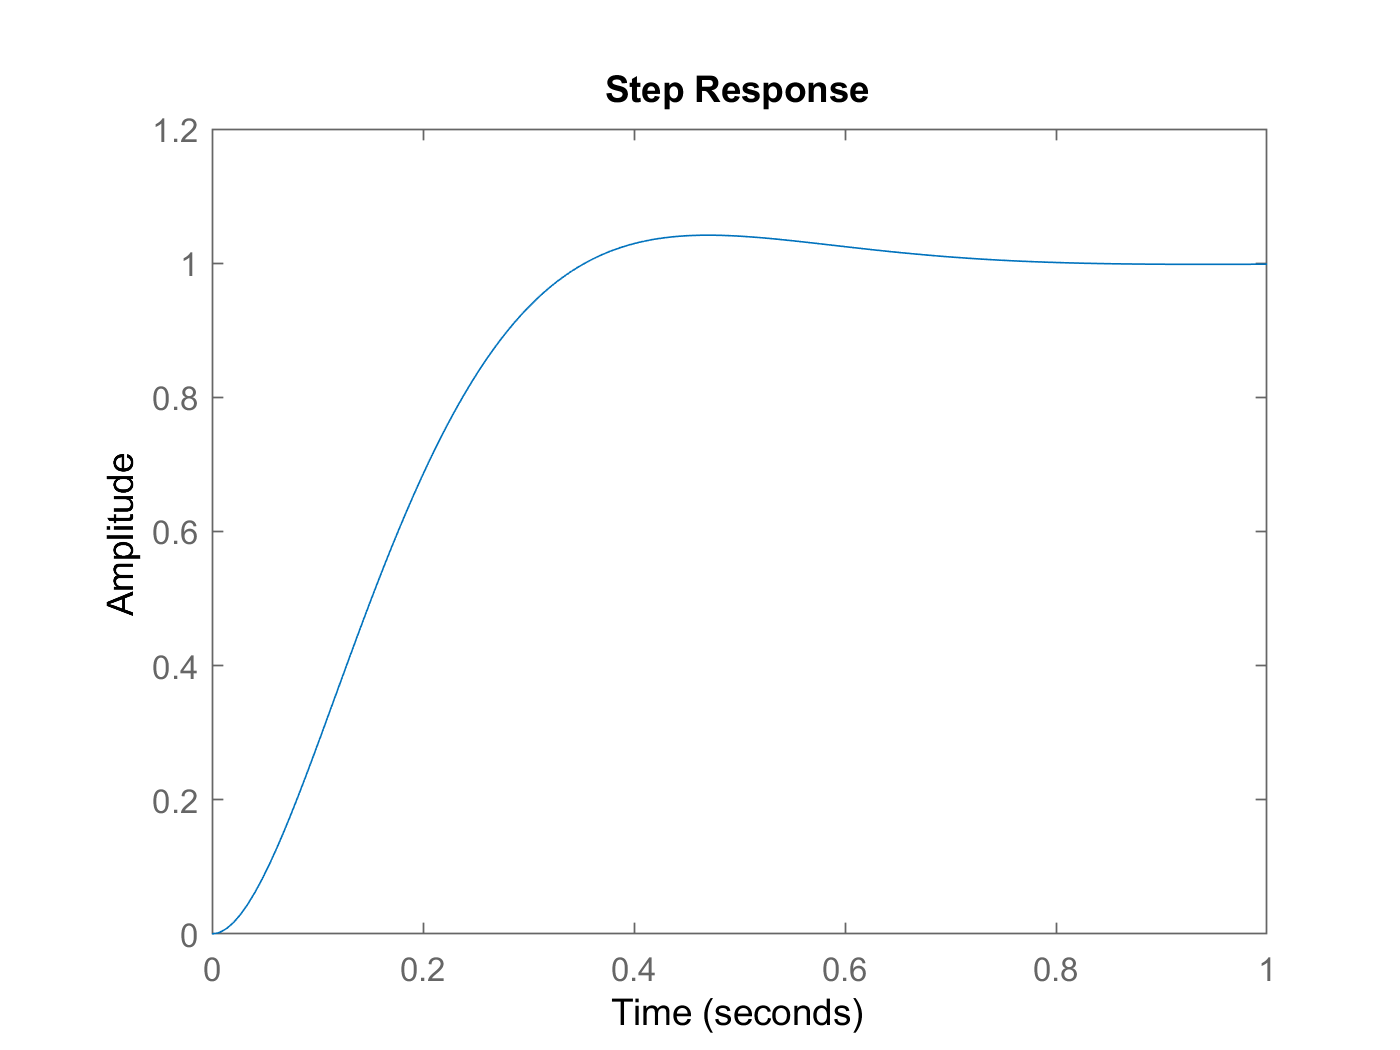

H1=7.5;
G_clbutterworth=(G_ol)*H1/(1+G_ol*H1);
step(G_clbutterworth)

stepinfo(G_clbutterworth)

ans = struct with fields:
        RiseTime: 0.2274
    SettlingTime: 0.6263
     SettlingMin: 0.9108
     SettlingMax: 1.0417
       Overshoot: 4.1723
      Undershoot: 0
            Peak: 1.0417
        PeakTime: 0.4703


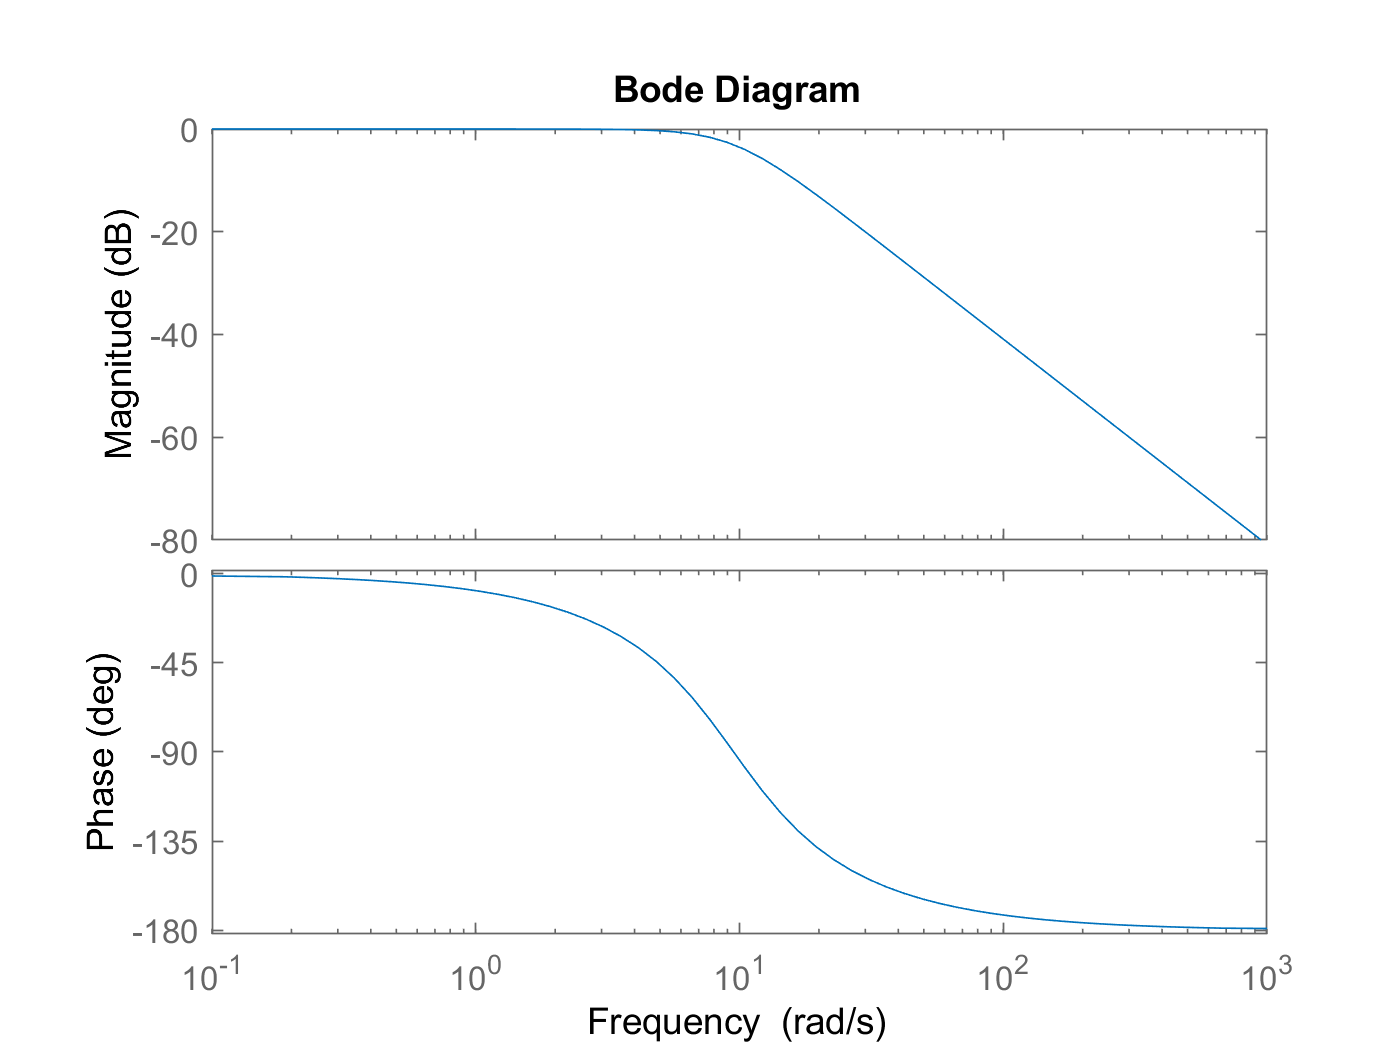

bode(G_clbutterworth)

damp(G_clbutterworth)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -6.76e+00 + 6.68e+00i     7.11e-01       9.50e+00         1.48e-01    
 -6.76e+00 - 6.68e+00i     7.11e-01       9.50e+00         1.48e-01    
 -1.35e+01                 1.00e+00       1.35e+01         7.40e-02    


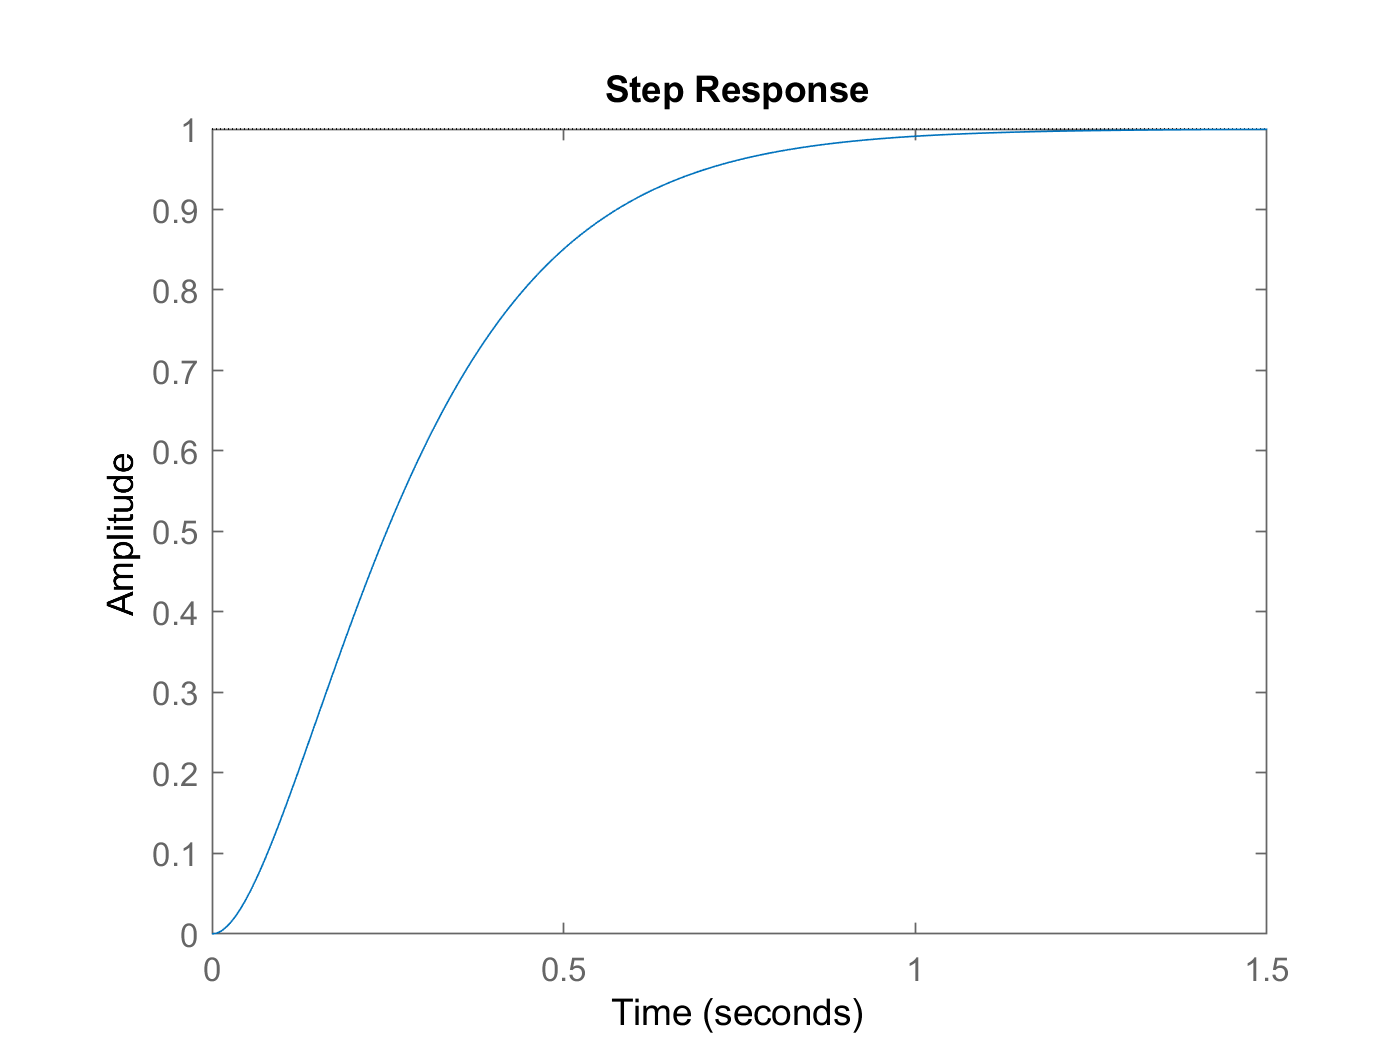


critical=tf(6.76^2,[1 2*6.76 6.76^2]);
step(critical)

stepinfo(critical)

ans = struct with fields:
        RiseTime: 0.4968
    SettlingTime: 0.8630
     SettlingMin: 0.9019
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 1.7644


%final controller stuff
GH=tf(0.89,[T_m 1 0]);

K_p=3.8;
closedloop=tf(0.89*K_p,[T_m 1 0.89*K_p]);
step(closedloop)
stepinfo(closedloop)

ans = struct with fields:
        RiseTime: 0.4964
    SettlingTime: 0.8621
     SettlingMin: 0.9023
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 1.7653


hold on
K_p=7.6;
closedloop=tf(0.89*K_p,[T_m 1 0.89*K_p]);
step(closedloop)
stepinfo(closedloop)

ans = struct with fields:
        RiseTime: 0.2246
    SettlingTime: 0.6238
     SettlingMin: 0.9040
     SettlingMax: 1.0434
       Overshoot: 4.3357
      Undershoot: 0
            Peak: 1.0434
        PeakTime: 0.4635


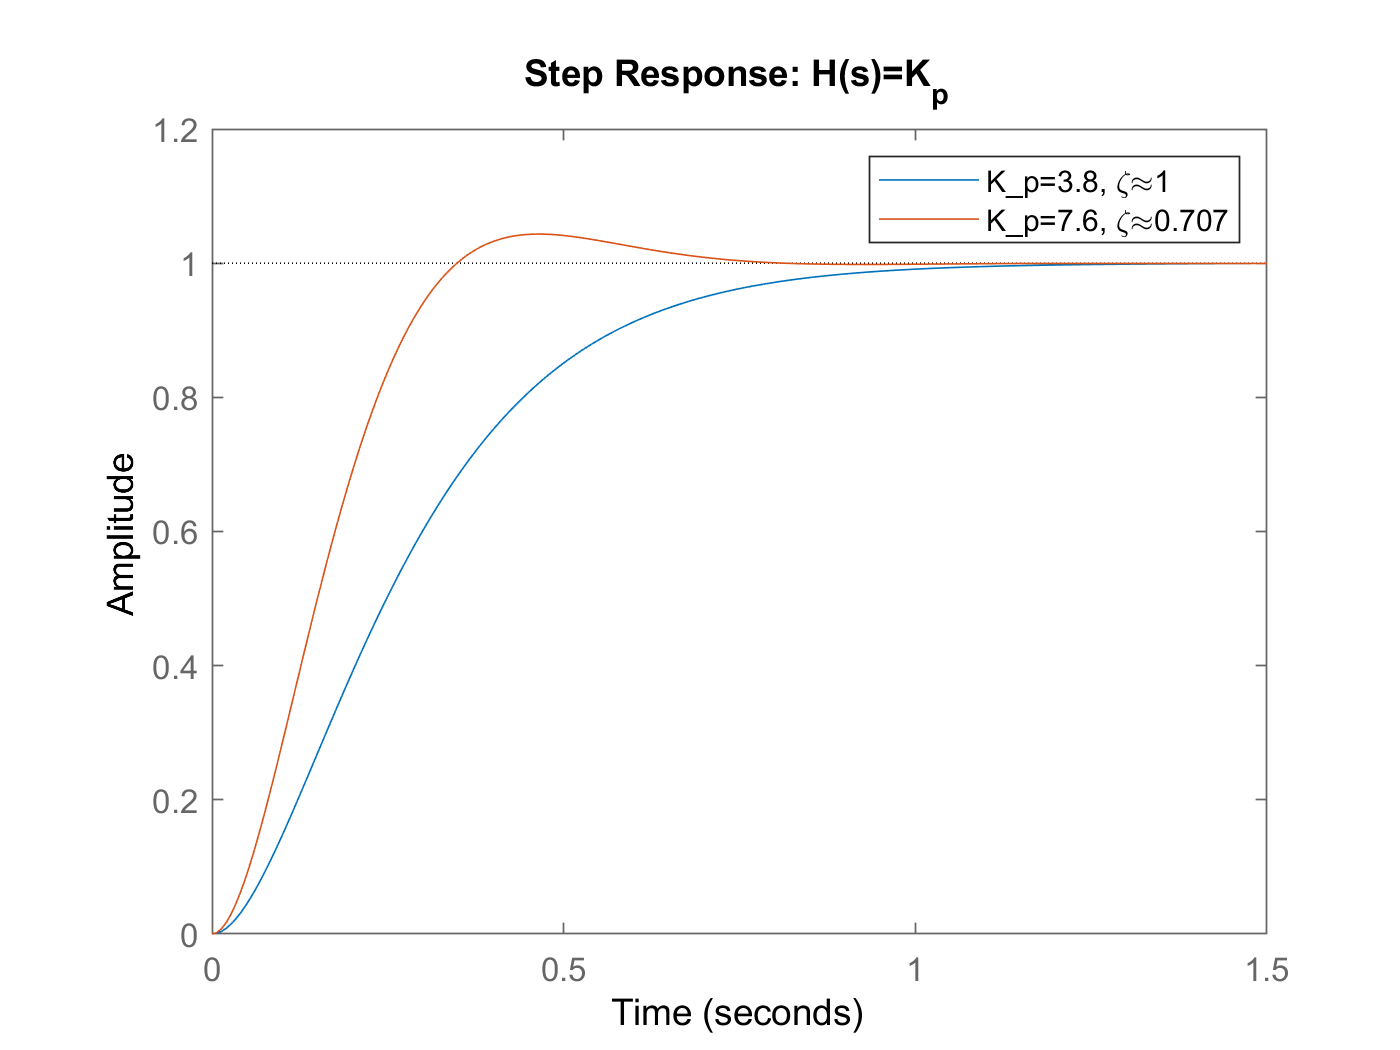

hold off
title("Step Response: H(s)=K_p")
legend("K_p=3.8, \zeta\approx1","K_p=7.6, \zeta\approx0.707")

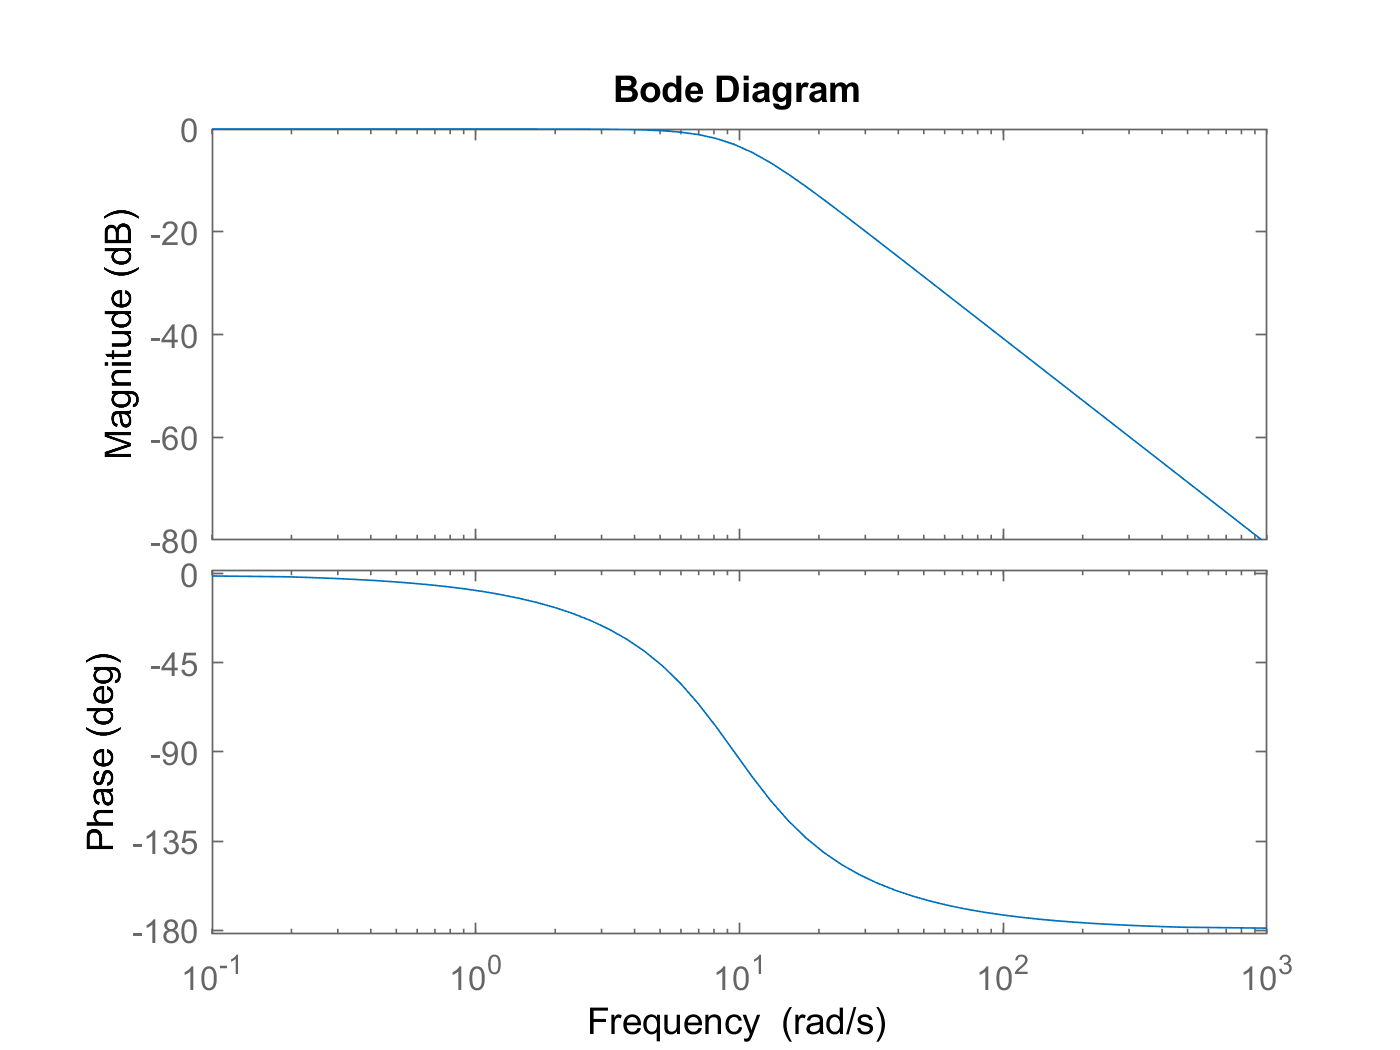


bode(closedloop)